Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Super-conducting dipole, defined by circle segments (Section 4.4.2)

Volker Ziemann, 211110, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

This example is very similar to `SCdipoleTwoCircles.mlx`, only the geometry is defined as an annular region that is calculated in a separate function `circlesegment()`, which is defined in the Appendix below. Please check there for the meaning of the input arguments.

clear all; close all
CS1=circlesegment(0.05,0.07,180-60,180+60,10); nn=length(CS1);
CS2=circlesegment(0.05,0.07,-60,60,10);
ws=0.2;   % World size
World=[2;4; -ws;ws;ws;-ws;-ws;-ws;ws;ws;zeros(nn-10,1)]; 

Now we assemble the geometry `g`, define the `model,` and attach the geometry to it...

gd=[World,CS1,CS2];  % assemble geometry
ns=char('World','CS1','CS2')';  % names of the regions                 
sf='World+CS1+CS2'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);

...and display the` EdgeLabels` before defining the boundary conditions` u =` $A_z=0$ on the outer boundaries of the `World`. 

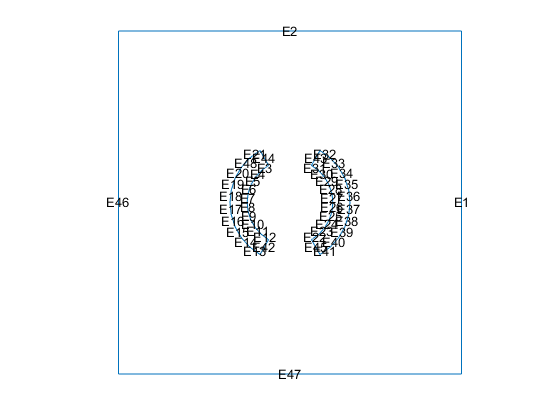

pdegplot(model,'EdgeLabels','on'); axis off; axis square;

applyBoundaryCondition(model,'Edge',[1,2,46,47],'u',0);

Once we know the SubDomainLabels we can specify the material properties, where we choose a current density of 500 A/mm^2. In this view the geometry of the coils is obvious.

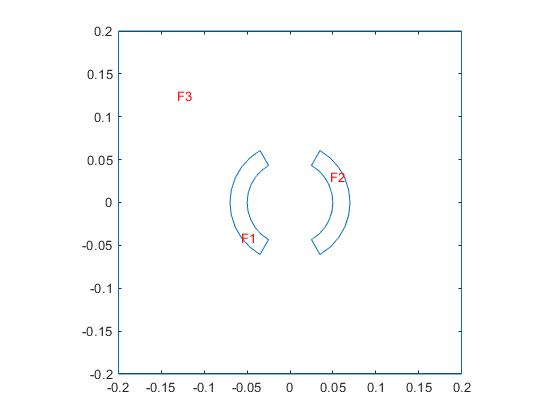

figure; pdegplot(model,'SubDomainLabels','on'); axis square;

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-628,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',628,'Face',2);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',3);

Then we generate the mesh, display it and solve the problem with` solvepde()`, which returns the `result,` a structure whose member `NodalSolution` provides us the value of` u = `$A_z$ on the mesh points.

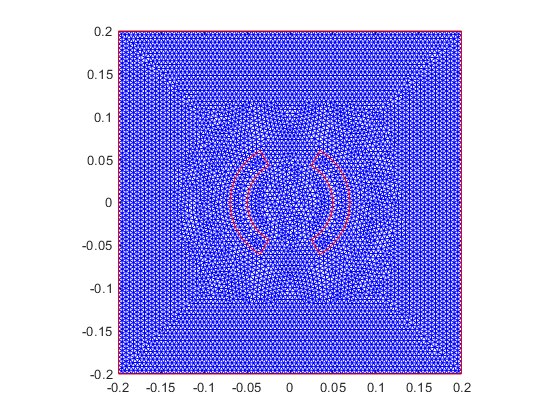

generateMesh(model,'Hmax',0.005);
figure; 
pdemesh(model); axis square;

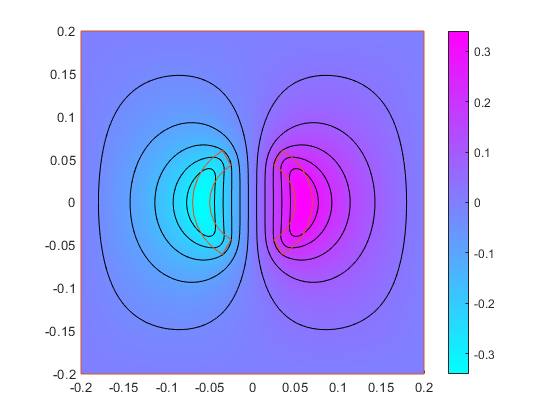

result=solvepde(model);
figure; pdeplot(model,'xydata',result.NodalSolution,'contour','on'); %axis equal
hold on; pdegplot(model)

As in previous examples we use the gradients to obtain the magnetic field components $B_x$ and $B_y$, which we plot them as arrows with `flowdata` and with `contour` lines and geometry superimposed.

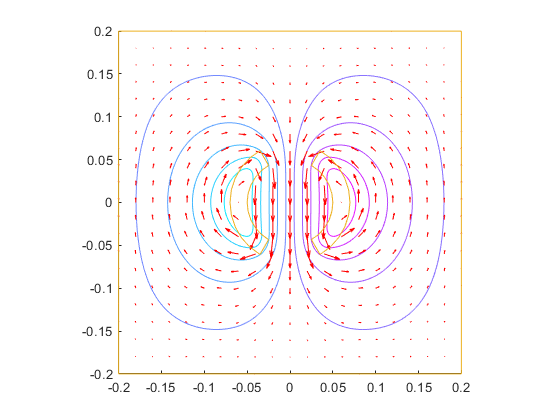

Bx=result.YGradients; By=-result.XGradients; 
figure; pdeplot(model,'xydata',result.NodalSolution,'xystyle','off', ...
  'flowdata',[Bx,By],'contour','on','colorbar','off'); 
hold on; pdegplot(model); axis equal; 

And the field in the mid-plane along the line, defined by x and y, is calculated and displayed with the following code

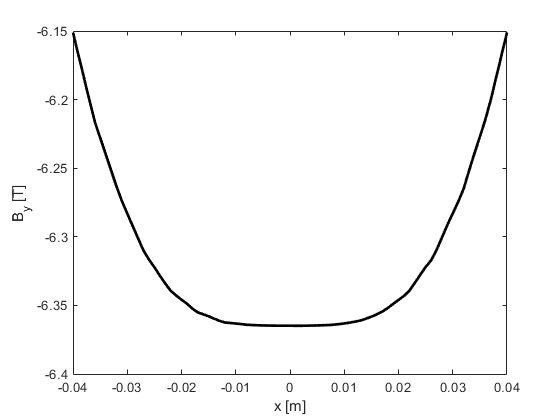

x=-0.04:0.001:0.04; y=zeros(1,length(x));
[dAx,dAy]=evaluateGradient(result,x,y); Bx=dAy; By=-dAx; B=hypot(Bx,By);
figure; plot(x,By,'k','LineWidth',2);
xlabel('x [m]'); ylabel('B_y [T]')

## Appendix

The function `circlesegment()` receives the following parameters as input

- `Ri`  = inner radius;

- `Ro` = outer radius;

- `phi1` = starting angle of the segment;

- `phi2` = ending angle of the segment;

- `N` = number of straight-line segment used to approximate the arcs;

It returns a column vector `cseg`  that describes a polygon describing the polygon. Inside the function *x*-ccordinates are calculated in the variables `xlist`, first on the inner radius and in the second loop over the outer radius.  Likewise contains `ylist` the *y*-coordinates. While calculating the points, the variable` ic` is incremented by one for each point. In the end a number 2, indicating a polygon , and the number of points `ic` is prepended to `xlist` and `ylist` and returned as `cseg`.

function cseg=circlesegment(Ri,Ro,phi1,phi2,N)
p1=phi1*pi/180; p2=phi2*pi/180;
dphi=(p2-p1)/N;
ic=0;
for k=0:N
  ic=ic+1;
  xlist(ic)=Ri*cos(p1+k*dphi); 
  ylist(ic)=Ri*sin(p1+k*dphi);
end
for k=0:N
  ic=ic+1;  
  xlist(ic)=Ro*cos(p2-k*dphi); 
  ylist(ic)=Ro*sin(p2-k*dphi);
end
cseg=[2;ic;xlist';ylist'];
end